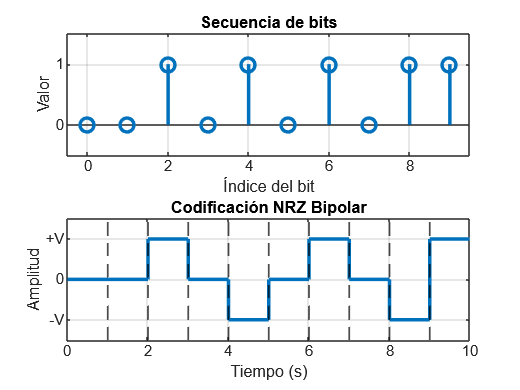

clc;    % Limpia la ventana de comandos
clear;  % Borra todas las variables del espacio de trabajo
close all; % Cierra todas las figuras abiertas

% --------------------------
% 1. Generación de la secuencia de bits
% --------------------------

% Secuencia binaria aleatoria de 10 bits
bit_seq = randi([0 1], 1, 10);

% Duración de cada bit en segundos
bit_duracion = 1;

% Frecuencia de muestreo
fs = 100;  

% Definir el eje de tiempo
t = 0:1/fs:length(bit_seq)*bit_duracion - 1/fs;

% Inicializar la señal en ceros
signal = zeros(size(t));

% -------------------------------
% 2. Construcción de la señal NRZ Bipolar
% -------------------------------

index = 1;  % Índice inicial
last_polarity = 1;  % Última polaridad utilizada para el bit "1"

for i = 1:length(bit_seq)
    if bit_seq(i) == 1
        % Alternar polaridad para cada bit "1"
        signal(index:index+fs-1) = last_polarity;  
        last_polarity = -last_polarity;  % Cambiar polaridad
    else
        signal(index:index+fs-1) = 0;  % Bit "0" es nivel 0V
    end
    index = index + fs;  % Avanzar en el tiempo
end

% -------------------------
% 3. Creación de la figura
% -------------------------

figure;  % Crear una nueva figura

% -------------------------------
% Subplot 1: Representación de la secuencia de bits
% -------------------------------
subplot(2,1,1); 
stem(0:length(bit_seq)-1, bit_seq, 'LineWidth', 2, 'MarkerSize', 8); 
ylim([-0.5 1.5]); 
xlim([-0.5 length(bit_seq)-0.5]);  
yticks([0 1]); 
yticklabels({'0', '1'}); 
xlabel('Índice del bit'); 
ylabel('Valor');  
title('Secuencia de bits');  
grid on; 

% -------------------------------
% Subplot 2: Señal NRZ Bipolar
% -------------------------------
subplot(2,1,2);  
stairs(t, signal, 'LineWidth', 2);
ylim([-1.5 1.5]); 
xlim([0 length(bit_seq)*bit_duracion]);  
yticks([-1 0 1]); 
yticklabels({'-V', '0', '+V'});  
xlabel('Tiempo (s)'); 
ylabel('Amplitud');  
title('Codificación NRZ Bipolar');
grid on; 
hold on;  

% Líneas verticales para separar los bits en la señal codificada
for i = 1:length(bit_seq)-1
    xline(i*bit_duracion, '--k', 'LineWidth', 1);  % Línea punteada negra
end

hold off;  